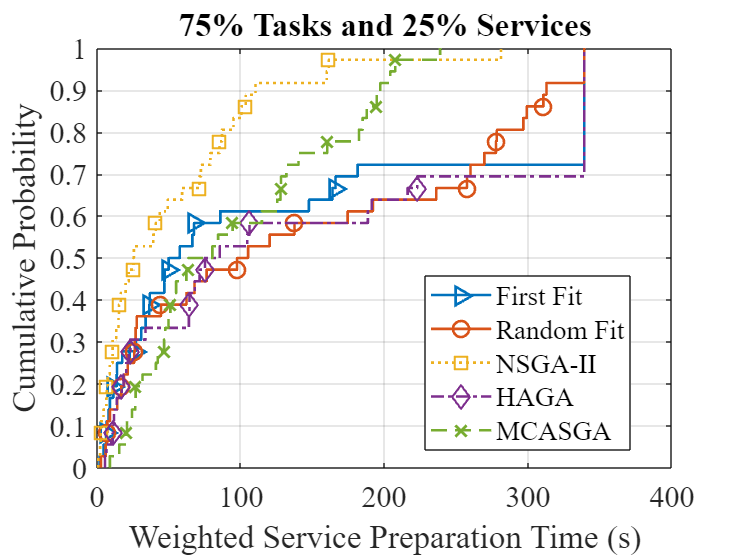

svc_file = fopen('svc_cdf.csv');
task_file = fopen('task_cdf.csv');


svcs = textscan(svc_file, '%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(svc_file);
tasks = textscan(task_file, '%f%f%f%f%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(task_file);

first_fit_svc = deal(svcs{1});
random_fit_svc = deal(svcs{2});
nsgaii_svc = deal(svcs{3});
haga_svc = deal(svcs{4});
mcasga_svc = deal(svcs{5});

first_fit_task = deal(tasks{1});
random_fit_task = deal(tasks{2});
nsgaii_task = deal(tasks{3});
haga_task = deal(tasks{4});
mcasga_task = deal(tasks{5});

first_fit_all = [first_fit_svc;first_fit_task];
random_fit_all = [random_fit_svc;random_fit_task];
nsgaii_all = [nsgaii_svc;nsgaii_task];
haga_all = [haga_svc;haga_task];
mcasga_all = [mcasga_svc;mcasga_task];


set(groot,'defaultLineMarkerSize',8);

cdf_first_fit_svc = cdfplot(first_fit_svc);
hold on;
cdf_random_fit_svc = cdfplot(random_fit_svc);
cdf_nsgaii_svc = cdfplot(nsgaii_svc);
cdf_haga_svc = cdfplot(haga_svc);
cdf_mcasga_svc = cdfplot(mcasga_svc);

cdf_first_fit_svc.Marker=">";
cdf_first_fit_svc.MarkerIndices=1:7:max(first_fit_svc)*3;
% fprintf('%d\n', max(first_fit_svc));
cdf_random_fit_svc.Marker="o";
cdf_random_fit_svc.MarkerIndices=1:7:max(random_fit_svc)*3;
cdf_nsgaii_svc.Marker="square";
cdf_nsgaii_svc.MarkerIndices=1:7:max(nsgaii_svc)*3;
cdf_haga_svc.Marker="diamond";
cdf_haga_svc.MarkerIndices=1:7:max(haga_svc)*3;
cdf_mcasga_svc.Marker="x";
cdf_mcasga_svc.MarkerIndices=1:7:max(mcasga_svc)*3;
set(cdf_first_fit_svc,'LineStyle', '-', 'LineWidth',1.3);
set(cdf_random_fit_svc,'LineStyle', '-', 'LineWidth',1.3);
set(cdf_nsgaii_svc,'LineStyle', ':', 'LineWidth',1.3);
set(cdf_haga_svc,'LineStyle', '-.', 'LineWidth',1.3);
set(cdf_mcasga_svc,'LineStyle', '--', 'LineWidth',1.3);

set(gca, 'Fontname', 'Times New Roman','FontSize',15);

xlabel('Weighted Service Preparation Time (s)');
ylabel('Cumulative Probability');
% here, even the end is 11, the picture only has 10, because no data bigger than 10
% xticks(0:0.5:11); 
yticks(0:0.1:1);
%xticklabels([0 10 20 30 40 50 60 70 80 90 100]);

% xlim(gca, [0 2]);
%set(gca, 'xlim', [0 4]);

legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');

title('75% Tasks and 25% Services');
hold off;



cdf_first_fit_task = cdfplot(first_fit_task);

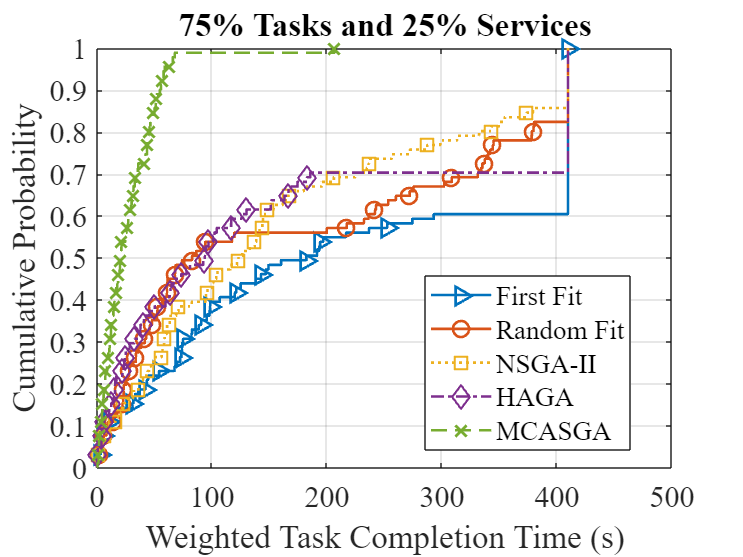

hold on;
cdf_random_fit_task = cdfplot(random_fit_task);
cdf_nsgaii_task = cdfplot(nsgaii_task);
cdf_haga_task = cdfplot(haga_task);
cdf_mcasga_task = cdfplot(mcasga_task);

cdf_first_fit_task.Marker=">";
cdf_first_fit_task.MarkerIndices=1:7:max(first_fit_task)*3;
% fprintf('%d\n', max(first_fit_task));
cdf_random_fit_task.Marker="o";
cdf_random_fit_task.MarkerIndices=1:7:max(random_fit_task)*3;
cdf_nsgaii_task.Marker="square";
cdf_nsgaii_task.MarkerIndices=1:7:max(nsgaii_task)*3;
cdf_haga_task.Marker="diamond";
cdf_haga_task.MarkerIndices=1:7:max(haga_task)*3;
cdf_mcasga_task.Marker="x";
cdf_mcasga_task.MarkerIndices=1:7:max(mcasga_task)*3;
set(cdf_first_fit_task,'LineStyle', '-', 'LineWidth',1.3);
set(cdf_random_fit_task,'LineStyle', '-', 'LineWidth',1.3);
set(cdf_nsgaii_task,'LineStyle', ':', 'LineWidth',1.3);
set(cdf_haga_task, 'LineStyle', '-.', 'LineWidth',1.3);
set(cdf_mcasga_task,'LineStyle', '--', 'LineWidth',1.3);

set(gca, 'Fontname', 'Times New Roman','FontSize',15);

xlabel('Weighted Task Completion Time (s)');
ylabel('Cumulative Probability');
% here, even the end is 11, the picture only has 10, because no data bigger than 10
% xticks(0:0.5:11); 
yticks(0:0.1:1);
%xticklabels([0 10 20 30 40 50 60 70 80 90 100]);

% xlim(gca, [0 2]);
%set(gca, 'xlim', [0 4]);

legend('First Fit', 'Random Fit', 'NSGA-II', 'HAGA', 'MCASGA', 'Location','best');

title('75% Tasks and 25% Services');
hold off;



% cdf_first_fit_all = cdfplot(first_fit_all);
% hold on;
% cdf_random_fit_all = cdfplot(random_fit_all);
% cdf_mcasga_all = cdfplot(mcasga_all);
% 
% set(cdf_first_fit_all,'LineStyle', '-', 'LineWidth',1.3);
% set(cdf_random_fit_all,'LineStyle', ':', 'LineWidth',1.3);
% set(cdf_mcasga_all,'LineStyle', '--', 'LineWidth',1.3);
% 
% set(gca, 'Fontname', 'Times New Roman','FontSize',15);
% 
% xlabel('Weighted Application Comsuming Time');
% ylabel('Cumulative Probability');
% % here, even the end is 11, the picture only has 10, because no data bigger than 10
% % xticks(0:0.5:11); 
% yticks(0:0.1:1);
% %xticklabels([0 10 20 30 40 50 60 70 80 90 100]);
% 
% % xlim(gca, [0 2]);
% %set(gca, 'xlim', [0 4]);
% 
% legend('First Fit', 'Random Fit', 'MCASGA', 'Location','best');
% 
% title('');
% hold off;


